## 3 Assignment

### 3.1 Classification with a single-layer perceptron

#### 3.1.1 Generation of linearly-separable data

Draw two sets of points/patterns in 2D from multivariate normal distribution.

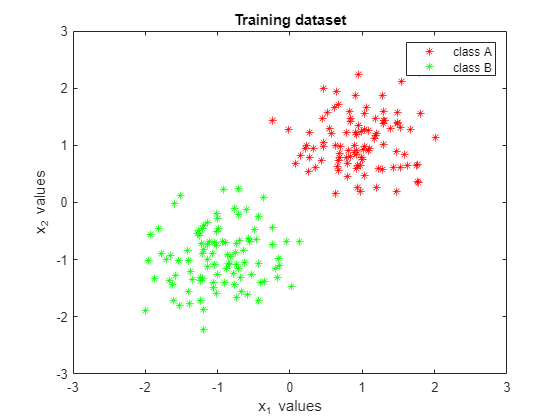

% Below lines are based from instruction, but mA, mB, sigmaA and sigmaB
% have been changed
n = 100;
mA = [ 1.0, 1.0]; sigmaA = 0.5;
mB = [-1.0, -1.0]; sigmaB = 0.5;
classA(1,:) = randn(1,n) .* sigmaA + mA(1);
classA(2,:) = randn(1,n) .* sigmaA + mA(2);
classB(1,:) = randn(1,n) .* sigmaB + mB(1);
classB(2,:) = randn(1,n) .* sigmaB + mB(2);

% Our code
pos_x1=classA(1,:);
pos_x2=classA(2,:);
plot(pos_x1,pos_x2,"r*")
hold on

neg_x1=classB(1,:);
neg_x2=classB(2,:);
plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('Training dataset') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
legend('class A','class B');
hold on

How to shuffle  

% randperm(3) % Prepare random index: 1 - 3 (no 0)
A =[1,3,5;2,4,6]

A =      1     3     5
     2     4     6



B = A(:, randperm(3))

B =      1     3     5
     2     4     6


%Same as -> B = A(:,[2,1,3])
clear A
clear B

Prepare the big X matrix and T matrix

classPos = [classA; ones(1,n)];
classNeg = [classB; -1*ones(1,n)];
dataset = [classPos, classNeg];
dataset = dataset(:, randperm(2*n));
X = dataset([1,2],:);
T = dataset(3,:);
X = [X; ones(1,n*2)]; %X_extend with a line of 1 for threshold


### 3.1.2 Classification with a single-layer perceptron and analysis

W_init=randn(1,3);

percpetron learning rules

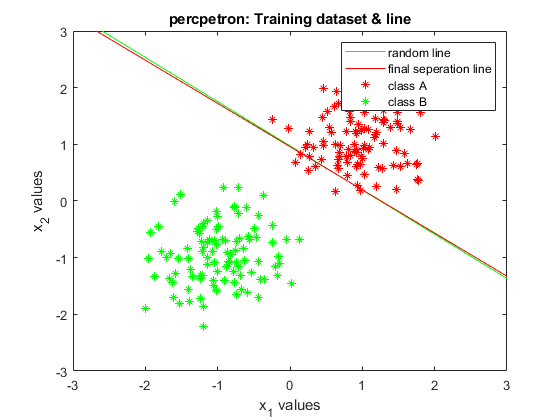

% Init W
W=W_init;

% Learning rate
eta = 0.001; % 0.001 is too small. Need more loops

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color       
hold on

for index=1:length(X)

    x = [dataset([1,2],index);1];
    t = dataset(3,index);

    W = perceptron_rule_one_sample(x, W, t, eta);
end

x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'r-') % final line in red color        
hold on

plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('percpetron: Training dataset & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
legend('random line','final seperation line','class A','class B');
hold on

online delta learning rules

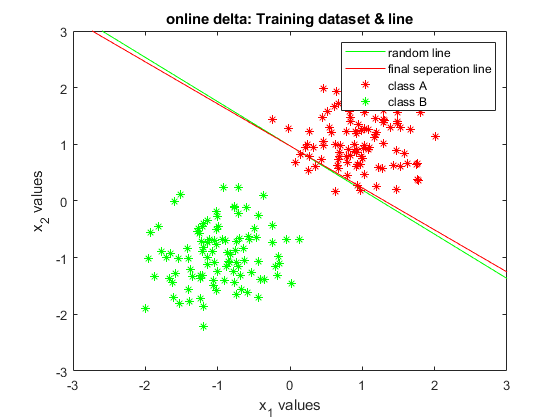

% Init W
W=W_init;
% Learning rate
eta = 0.001; % 0.001 is too small. Need more loops

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color       
hold on

for index=1:length(X)

    x = [dataset([1,2],index);1];
    t = dataset(3,index);

    W = delta_rule_one_sample(x, W, t, eta);
end

x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'r-') % final line in red color          
hold on

plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('online delta: Training dataset & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
legend('random line','final seperation line','class A','class B');
hold on

batch delta (5 epoch)

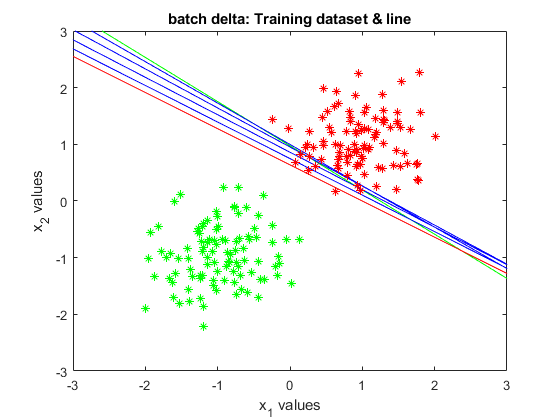

% Init W
W=W_init;
% Learning rate
eta = 0.001;
epoch = 5;

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color         
hold on

for index=1:epoch
    delta_W = - eta* (W*X-T)*X';
    W = W + delta_W;
    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'b-') % new line in blue color         
    hold on
end

    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'r-') % final line in red color           
    hold on

plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('batch delta: Training dataset & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on

batch delta (20 epoch)

% Init W
W=W_init;
% Learning rate
eta = 0.001;
epoch = 20;

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color         
hold on

for index=1:epoch
    delta_W = - eta* (W*X-T)*X';
    W = W + delta_W;
    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'b-') % new line in blue color         
    hold on
end

    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'r-') % final line in red color           
    hold on
W

W =     0.3929    0.5071   -0.0374


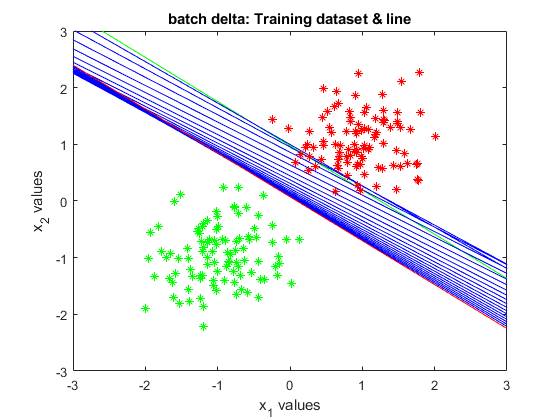


plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('batch delta no bias: Training dataset & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on

#### No bias 

batch delta (20 epoch)

% Init W
W=W_init([1,2]);
% X should be 2D
X = X([1,2],:);

X =     1.5434    0.0720    1.1760   -0.8544    1.0592    0.8983   -0.0472    1.2888    0.3193    0.0224    0.9176   -1.0141   -0.0167    0.6881   -1.0381   -1.0206   -1.1449   -1.0720   -0.8847    1.7743   -0.6365   -0.6769   -1.1355   -0.6015   -1.1941    0.9167    0.7864   -1.8164    0.6658   -0.8577   -1.2754    1.5214   -0.7725   -1.1453    0.7944    0.8373   -1.4065    0.9502    1.7499    1.1614   -1.2409    0.3528    0.8417    0.1487   -0.3655   -1.0185   -1.6602    1.0808    0.4375   -1.7782
    2.1140    0.6757    1.4618   -1.0597    1.6533    0.8714   -0.6816    1.3857    0.9389   -1.4644    0.9080   -1.5843    1.2767    0.7939   -1.0808   -0.5031   -0.3464   -0.8993   -1.1625    0.3565   -0.8337   -1.5607   -0.9913   -0.1214   -0.3940    1.1914    1.2278   -0.4464    1.7187   -0.9134   -0.5345    0.6104   -1.4390   -0.7351    0.6860    1.4093   -1.5568    2.2449    0.6385    1.1209   -1.3129    0.6063    1.4650    0.8188    0.0914   -0.1931   -1.3652    1.2590    0.7289   -0

% Learning rate
eta = 0.001;
epoch = 20;

figure
x_1 = linspace(-5,5,9);
x_2 = (-W(1)*x_1)/W(2);
plot(x_1,x_2,'g-') % random line in green color         
hold on

for index=1:epoch
    delta_W = - eta* (W*X-T)*X';
    W = W + delta_W;
    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1))/W(2);  % No W(3)
    plot(x_1,x_2,'b-') % new line in blue color         
    hold on
end

    x_1 = linspace(-5,5,9);
    x_2 = (-W(1)*x_1)/W(2);
    plot(x_1,x_2,'r-') % final line in red color           
    hold on

W

W =     0.4127    0.4871


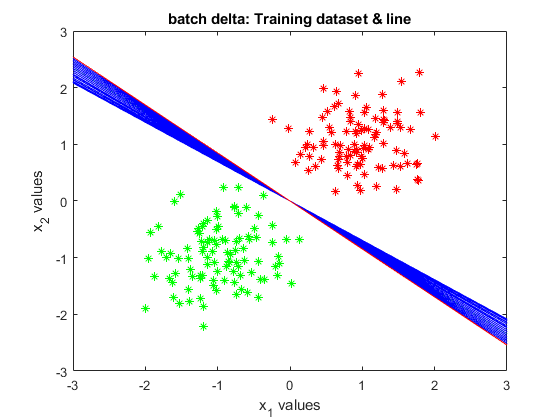


plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('batch delta: Training dataset & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on

#### 3.1.3 Classi�cation of samples that are not linearly separable

#### 3.1.3.1 non-linearly separable dataset

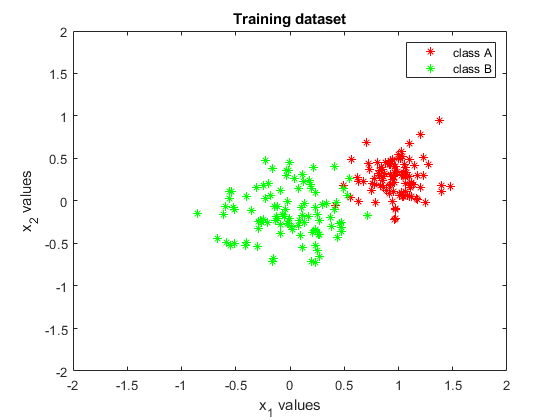


% Below lines are based from instruction, but mA, mB, sigmaA and sigmaB
% have been changed
n = 100;
mA = [ 1.0, 0.3]; sigmaA = 0.2;
mB = [0.0, -0.1]; sigmaB = 0.3;
classA(1,:) = randn(1,n) .* sigmaA + mA(1);
classA(2,:) = randn(1,n) .* sigmaA + mA(2);
classB(1,:) = randn(1,n) .* sigmaB + mB(1);
classB(2,:) = randn(1,n) .* sigmaB + mB(2);

% Our code
figure
pos_x1=classA(1,:);
pos_x2=classA(2,:);
plot(pos_x1,pos_x2,"r*")
hold on

neg_x1=classB(1,:);
neg_x2=classB(2,:);
plot(neg_x1,neg_x2,"g*")

xlim([-2,2])
ylim([-2,2])
title('Training dataset') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
legend('class A','class B');
hold on

Prepare the big X matrix and T matrix

classPos = [classA; ones(1,n)];
classNeg = [classB; -1*ones(1,n)];
dataset = [classPos, classNeg];
dataset = dataset(:, randperm(2*n));
X = dataset([1,2],:);
T = dataset(3,:);
X = [X; ones(1,n*2)]; %X_extend with a line of 1 for threshold

batch delta (20 epoch)

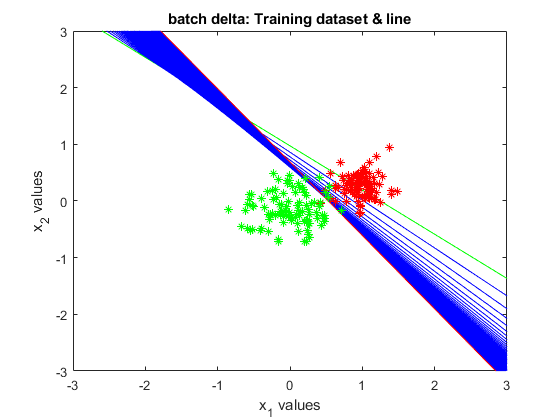

% Init W
W=W_init;
% Learning rate
eta = 0.001;
epoch = 40;

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color         
hold on

for index=1:epoch
    delta_W = - eta* (W*X-T)*X';
    W = W + delta_W;
    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'b-') % new line in blue color         
    hold on
end

    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'r-') % final line in red color           
    hold on

plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('batch delta: Training dataset & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on

#### 3.1.3.2 non-linearly separable dataset (remove 25% from A and 25% from B)

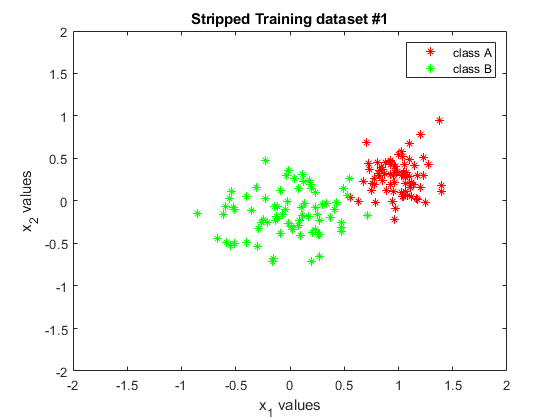


% Below lines are based from instruction, but mA, mB, sigmaA and sigmaB
% have been changed
%n = 100;
%mA = [ 1.0, 0.3]; sigmaA = 0.2;
%mB = [0.0, -0.1]; sigmaB = 0.3;
classA_tmp = classA;
classB_tmp = classB;
classA_tmp = classA_tmp(:, randperm(n, 0.75*n));
classB_tmp = classB_tmp(:, randperm(n, 0.75*n));
% https://ww2.mathworks.cn/help/matlab/ref/randperm.html?lang=en 

% Our code
figure
pos_x1=classA_tmp(1,:);
pos_x2=classA_tmp(2,:);
plot(pos_x1,pos_x2,"r*")
hold on

neg_x1=classB_tmp(1,:);
neg_x2=classB_tmp(2,:);
plot(neg_x1,neg_x2,"g*")

xlim([-2,2])
ylim([-2,2])
title('Stripped Training dataset #1') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
legend('class A','class B');
hold on

Prepare the big X matrix and T matrix

classPos = [classA_tmp; ones(1,length(classA_tmp))];
classNeg = [classB_tmp; -1*ones(1,length(classB_tmp))];
dataset = [classPos, classNeg];
dataset = dataset(:, randperm(length(dataset)));
X = dataset([1,2],:);
T = dataset(3,:);
X = [X; ones(1,length(X))]; %X_extend with a line of 1 for threshold

batch delta (20 epoch)

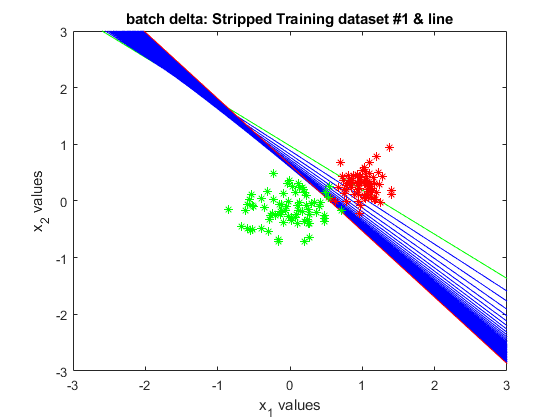

% Init W
W=W_init;
% Learning rate
eta = 0.001;
epoch = 40;

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color         
hold on

for index=1:epoch
    delta_W = - eta* (W*X-T)*X';
    W = W + delta_W;
    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'b-') % new line in blue color         
    hold on
end

    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'r-') % final line in red color           
    hold on

plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('batch delta: Stripped Training dataset #1 & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on

#### 3.1.3.3  non-linearly separable dataset (remove 50% from A )

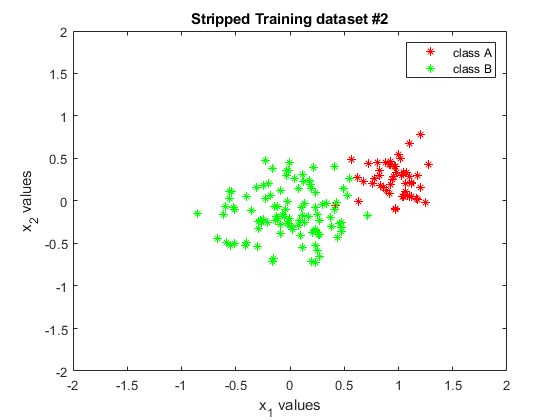


% Below lines are based from instruction, but mA, mB, sigmaA and sigmaB
% have been changed
%n = 100;
%mA = [ 1.0, 0.3]; sigmaA = 0.2;
%mB = [0.0, -0.1]; sigmaB = 0.3;
classA_tmp = classA;
classB_tmp = classB;
classA_tmp = classA_tmp(:, randperm(n, 0.50*n));
% https://ww2.mathworks.cn/help/matlab/ref/randperm.html?lang=en 

% Our code
figure
pos_x1=classA_tmp(1,:);
pos_x2=classA_tmp(2,:);
plot(pos_x1,pos_x2,"r*")
hold on

neg_x1=classB_tmp(1,:);
neg_x2=classB_tmp(2,:);
plot(neg_x1,neg_x2,"g*")

xlim([-2,2])
ylim([-2,2])
title('Stripped Training dataset #2') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
legend('class A','class B');
hold on

Prepare the big X matrix and T matrix

classPos = [classA_tmp; ones(1,length(classA_tmp))];
classNeg = [classB_tmp; -1*ones(1,length(classB_tmp))];
dataset = [classPos, classNeg];
dataset = dataset(:, randperm(length(dataset)));
X = dataset([1,2],:);
T = dataset(3,:);
X = [X; ones(1,length(X))]; %X_extend with a line of 1 for threshold

batch delta (20 epoch)

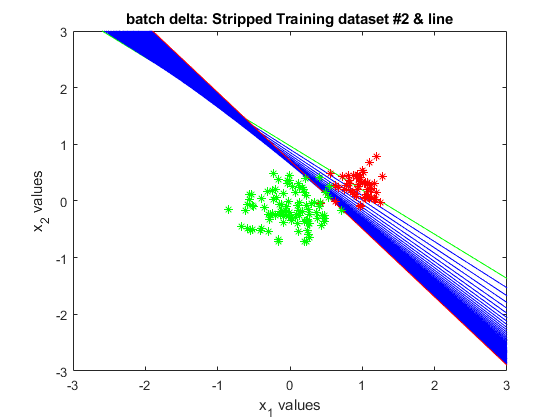

% Init W
W=W_init;
% Learning rate
eta = 0.001;
epoch = 40;

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color         
hold on

for index=1:epoch
    delta_W = - eta* (W*X-T)*X';
    W = W + delta_W;
    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'b-') % new line in blue color         
    hold on
end

    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'r-') % final line in red color           
    hold on

plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('batch delta: Stripped Training dataset #2 & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on

#### 3.1.3.4 non-linearly separable dataset (remove 50% from B)

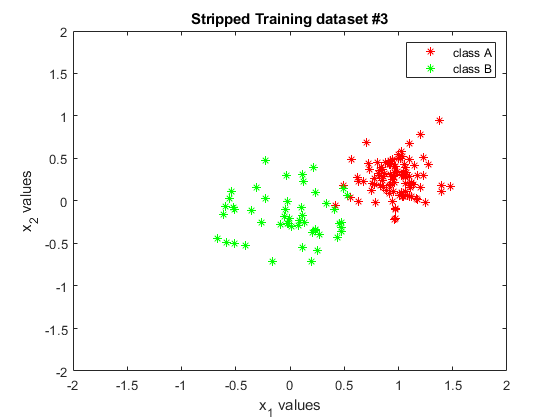


% Below lines are based from instruction, but mA, mB, sigmaA and sigmaB
% have been changed
%n = 100;
%mA = [ 1.0, 0.3]; sigmaA = 0.2;
%mB = [0.0, -0.1]; sigmaB = 0.3;
classA_tmp = classA;
classB_tmp = classB;
classB_tmp = classB_tmp(:, randperm(n, 0.50*n));
% https://ww2.mathworks.cn/help/matlab/ref/randperm.html?lang=en 

% Our code
figure
pos_x1=classA_tmp(1,:);
pos_x2=classA_tmp(2,:);
plot(pos_x1,pos_x2,"r*")
hold on

neg_x1=classB_tmp(1,:);
neg_x2=classB_tmp(2,:);
plot(neg_x1,neg_x2,"g*")

xlim([-2,2])
ylim([-2,2])
title('Stripped Training dataset #3') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
legend('class A','class B');
hold on

Prepare the big X matrix and T matrix

classPos = [classA_tmp; ones(1,length(classA_tmp))];
classNeg = [classB_tmp; -1*ones(1,length(classB_tmp))];
dataset = [classPos, classNeg];
dataset = dataset(:, randperm(length(dataset)));
X = dataset([1,2],:);
T = dataset(3,:);
X = [X; ones(1,length(X))]; %X_extend with a line of 1 for threshold

batch delta (20 epoch)

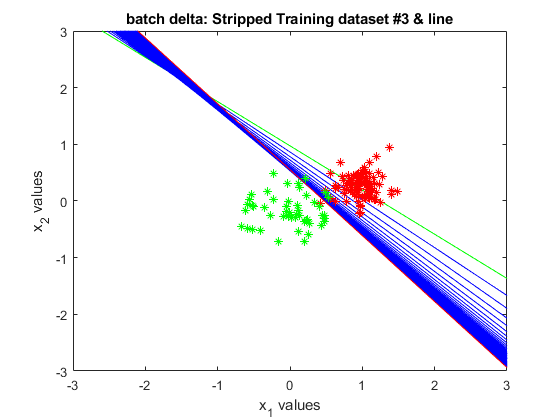

% Init W
W=W_init;
% Learning rate
eta = 0.001;
epoch = 40;

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color         
hold on

for index=1:epoch
    delta_W = - eta* (W*X-T)*X';
    W = W + delta_W;
    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'b-') % new line in blue color         
    hold on
end

    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'r-') % final line in red color           
    hold on

plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('batch delta: Stripped Training dataset #3 & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on

#### 3.1.3.5 non-linearly separable dataset (special)


% Below lines are based from instruction, but mA, mB, sigmaA and sigmaB
% have been changed
%n = 100;
%mA = [ 1.0, 0.3]; sigmaA = 0.2;
%mB = [0.0, -0.1]; sigmaB = 0.3;
classA_tmp = classA;
classB_tmp = classB;

pos_x1=classA_tmp(1,:);
classA_tmp_left = classA_tmp(:,pos_x1 <0)


classA_tmp_left =

  2×0 empty double matrix



classA_tmp_right =  classA_tmp(:,pos_x1 >0)

classA_tmp_right =     1.1789    0.6766    1.0669    1.1033    0.6235    0.9495    0.7602    1.1046    1.0496    1.0003    0.9279    0.8570    0.8202    0.9667    0.8600    0.5638    0.7477    0.8870    0.7352    1.1042    0.8796    1.1211    0.8479    0.9530    0.9493    1.0865    0.9466    1.1988    0.4914    1.0980    1.3821    1.0579    1.0064    0.9720    1.1216    1.0382    1.1743    1.2305    0.7271    1.1153    0.8094    0.9933    0.9207    1.0645    1.3963    1.0599    0.7810    0.9685    0.7030    0.9129
    0.0227    0.2333    0.3169    0.4828    0.2804    0.2832    0.2090    0.6786    0.0509    0.4955    0.1962    0.3655    0.3263    0.3328    0.1569    0.4903    0.1248    0.1224    0.3679    0.0478    0.4586    0.0578    0.2467    0.1099    0.3057    0.0602    0.2546    0.7817    0.1831    0.1797    0.9465    0.4291    0.0653   -0.2001    0.2231    0.5229    0.3056    0.2993    0.4356    0.2003    0.4560    0.3436    0.4446    0.3920    0.1141    0.2843    0.1996   -0.0869


classA_tmp_left = classA_tmp_left(:, randperm(length(classA_tmp_left), 0.80*length(classA_tmp_left)));
classA_tmp_right = classA_tmp_right(:, randperm(length(classA_tmp_right), 0.20*length(classA_tmp_right)));

classA_tmp = [classA_tmp_left classA_tmp_right]

classA_tmp =     0.7810    1.0717    1.0439    0.9466    1.0980    0.7352    1.1743    0.8673    1.0754    0.6766    0.9484    0.8479    1.1153    1.0268    0.9720    1.0865    1.0669    1.3963    1.0651    0.9530
    0.1996    0.3351    0.3352    0.2546    0.1797    0.3679    0.3056    0.3226    0.3400    0.2333   -0.0113    0.2467    0.2003    0.1004   -0.2001    0.0602    0.3169    0.1141    0.2079    0.1099


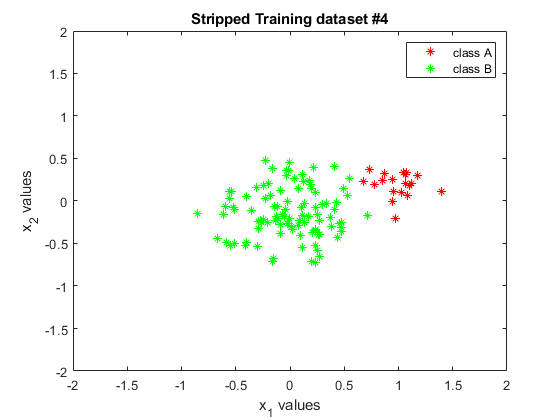

% https://ww2.mathworks.cn/help/matlab/ref/randperm.html?lang=en 

% Our code
figure
pos_x1=classA_tmp(1,:);
pos_x2=classA_tmp(2,:);
plot(pos_x1,pos_x2,"r*")
hold on

neg_x1=classB_tmp(1,:);
neg_x2=classB_tmp(2,:);
plot(neg_x1,neg_x2,"g*")

xlim([-2,2])
ylim([-2,2])
title('Stripped Training dataset #4') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
legend('class A','class B');
hold on

Prepare the big X matrix and T matrix

classPos = [classA_tmp; ones(1,length(classA_tmp))];
classNeg = [classB_tmp; -1*ones(1,length(classB_tmp))];
dataset = [classPos, classNeg];
dataset = dataset(:, randperm(length(dataset)));
X = dataset([1,2],:);
T = dataset(3,:);
X = [X; ones(1,length(X))]; %X_extend with a line of 1 for threshold

batch delta (20 epoch)

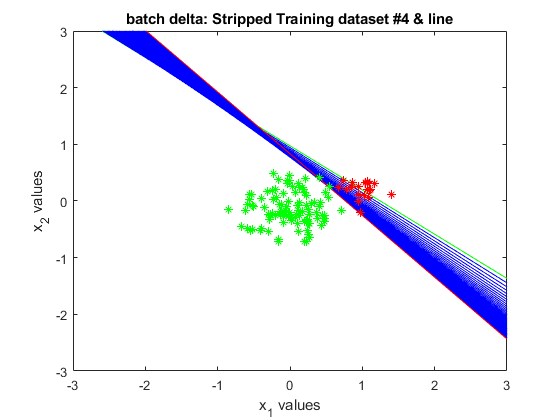

% Init W
W=W_init;
% Learning rate
eta = 0.001;
epoch = 40;

figure
x_1 = linspace(-5,5,9);
x_2 = ((-W(1)*x_1)-W(3))/W(2);
plot(x_1,x_2,'g-') % random line in green color         
hold on

for index=1:epoch
    delta_W = - eta* (W*X-T)*X';
    W = W + delta_W;
    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'b-') % new line in blue color         
    hold on
end

    x_1 = linspace(-5,5,9);
    x_2 = ((-W(1)*x_1)-W(3))/W(2);
    plot(x_1,x_2,'r-') % final line in red color           
    hold on

plot(pos_x1,pos_x2,"r*")
hold on

plot(neg_x1,neg_x2,"g*")

xlim([-3,3])
ylim([-3,3])
title('batch delta: Stripped Training dataset #4 & line') 
xlabel('x_1 values') % x-axis label
ylabel('x_2 values') % y-axis label
hold on